clear all;
close all;
%start time is May 24 2020 06:30:00
startTime = 20200524063000;
%end time is May 25 2020 15:00:00
endTime = 20200525150000;
%stn 045
stnID = 045;
gliderTable = readtable('metbuoy_26-04.csv');

cdipid = stnID; 
%convert startTime for cdip
    startTimestr = int2str(startTime);
    y_start = str2num(startTimestr(:,1:4));
    m_start = str2num(startTimestr(:,5:6));
    d_start = str2num(startTimestr(:,7:8));
    h_start = str2num(startTimestr(:,9:10));
    min_start = str2num(startTimestr(:,11:12));
    s_start = str2num(startTimestr(:,13:14));
    %convert endTime
    endTimestr = int2str(endTime);
    y_end = str2num(endTimestr(:,1:4));
    m_end = str2num(endTimestr(:,5:6));
    d_end = str2num(endTimestr(:,7:8));
    h_end = str2num(endTimestr(:,9:10));
    min_end = str2num(endTimestr(:,11:12));
    s_end = str2num(endTimestr(:,13:14));

tlims = [datenum(y_start,m_start,d_start,h_start,min_start,s_start) datenum(y_end, m_end,d_end,h_end,min_end,s_end)]; 

% spectral data etc. ------------------------------------------------------
clear cdip;
tres = 1;

varnm = 'Time';
[cdip.time] = dload_cdipvar(cdipid,varnm,tlims, tres);

---> Not using CDIP realtime



varnm = 'Hs';
[cdip.hs] = dload_cdipvar(cdipid,varnm,tlims, tres);

---> Not using CDIP realtime



varnm = 'Tp';
[cdip.tp] = dload_cdipvar(cdipid,varnm,tlims, tres);

---> Not using CDIP realtime



varnm = 'EnergyDensity';
[cdip.sf, cdip.f] = dload_cdipspec(cdipid,varnm,tlims, tres);

---> Not using CDIP realtime



varnm = 'MeanDirection';
[cdip.md] = dload_cdipspec(cdipid,varnm,tlims, tres);

---> Not using CDIP realtime



%get waveglider time and wind vectors for appropriate times
[wgt,wgWind,wgMeanDir,~] = gliderTime(gliderTable, startTime, endTime);

%remove waveglider times that have no corresonding values in energy times
t_wind_new = NaN(length(cdip.time),1);
wind_wave_indices = NaN(length(cdip.time),1);
diff = 1000;
index = 1;
    for i = 1:length(cdip.time)
      for j = 1:length(wgt)
        if abs(cdip.time(i)-wgt(j)) < diff
            diff = abs(cdip.time(i)-wgt(j));
            index = j;
        end
      end
      t_wind_new(i) = wgt(index);
      wind_wave_indices(i) = index;
      index = 1;
      diff = 1000;
    end    
%new wind speeds
wgWind = wgWind(wind_wave_indices);
%new mean direction
wgMeanDir = wgMeanDir(wind_wave_indices);
%new wind times
wgt = wgt(wind_wave_indices);

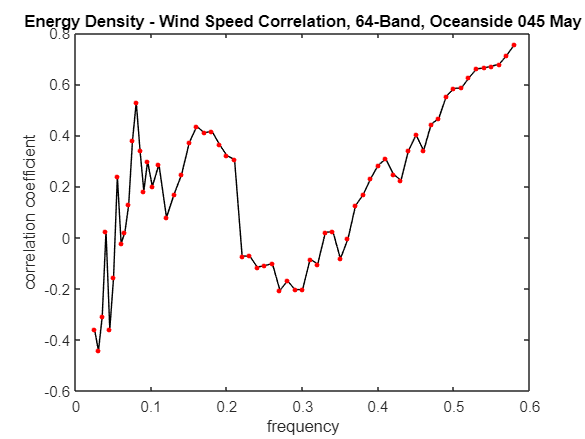

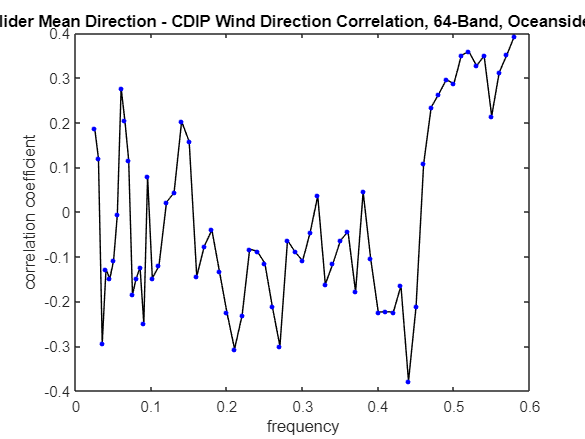

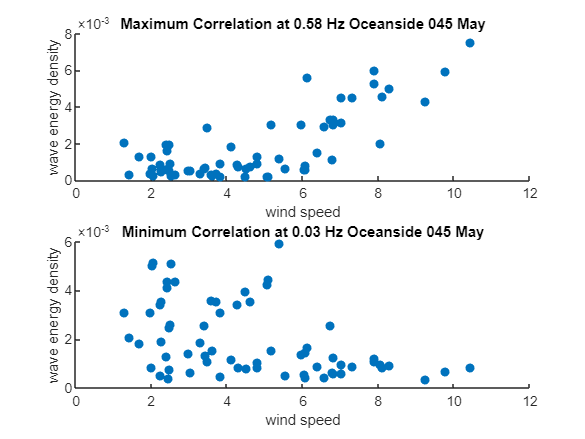

corr =    -0.3613   -0.4431   -0.3095    0.0244   -0.3588   -0.1570    0.2392   -0.0234    0.0212    0.1278    0.3786    0.5289    0.3404    0.1819    0.2982    0.1995    0.2862    0.0784    0.1691    0.2467    0.3702    0.4353    0.4096    0.4163    0.3645    0.3202    0.3050   -0.0727   -0.0718   -0.1155   -0.1098   -0.1014   -0.2065   -0.1692   -0.2040   -0.2026   -0.0839   -0.1036    0.0196    0.0244   -0.0828   -0.0047    0.1256    0.1672    0.2307    0.2832    0.3074    0.2482    0.2237    0.3398


dircorr =     0.1877    0.1201   -0.2936   -0.1277   -0.1495   -0.1090   -0.0057    0.2769    0.2037    0.1156   -0.1844   -0.1484   -0.1235   -0.2492    0.0798   -0.1480   -0.1206    0.0220    0.0430    0.2025    0.1573   -0.1441   -0.0762   -0.0402   -0.1328   -0.2256   -0.3062   -0.2309   -0.0828   -0.0881   -0.1142   -0.2120   -0.2997   -0.0634   -0.0892   -0.1091   -0.0454    0.0359   -0.1614   -0.1156   -0.0638   -0.0436   -0.1782    0.0448   -0.1045   -0.2236   -0.2228   -0.2236   -0.1650   -0.3782


[corr, dircorr] = windWaveCorr64(' Oceanside 045 May', wgWind, wgMeanDir, cdip)

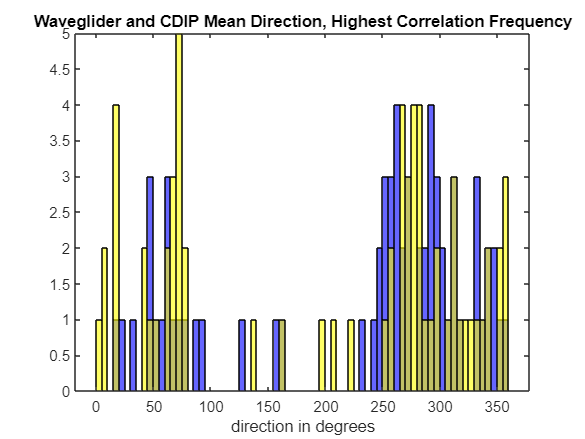

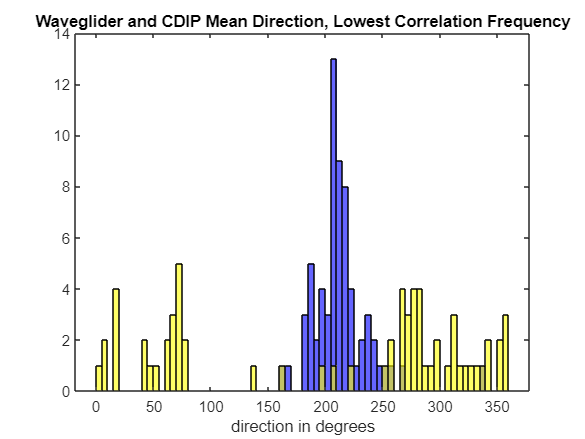

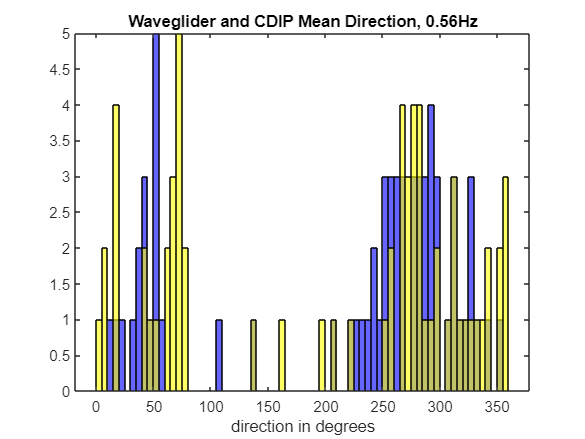

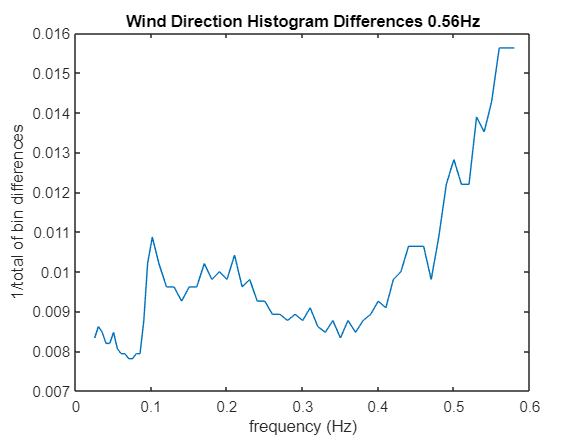

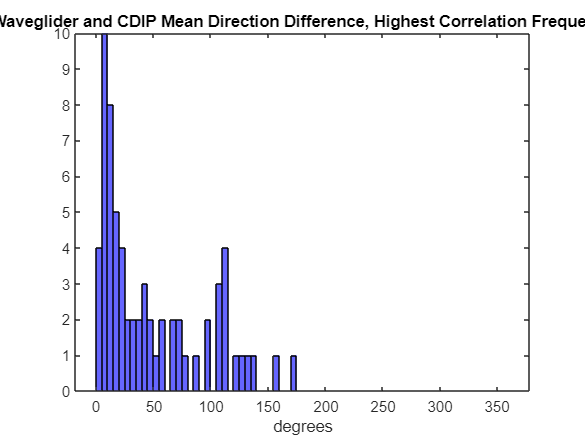

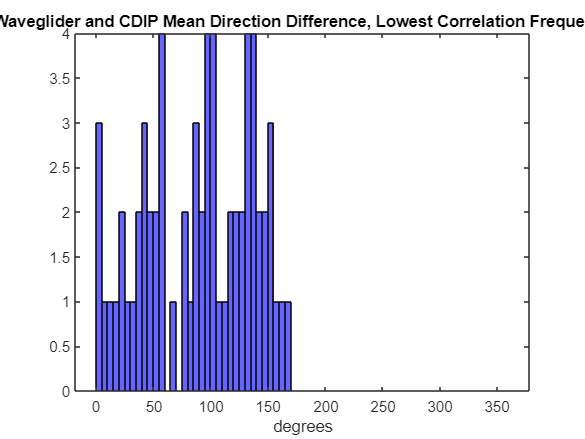

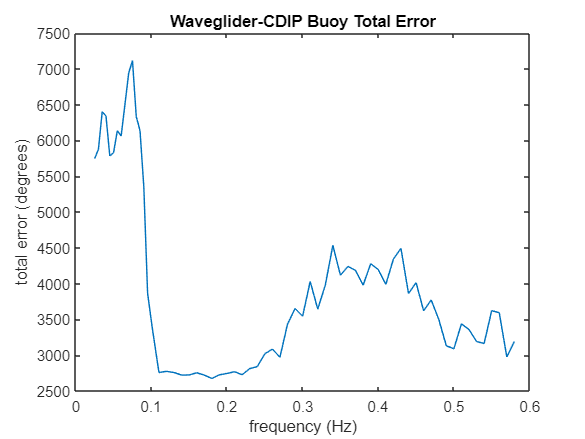

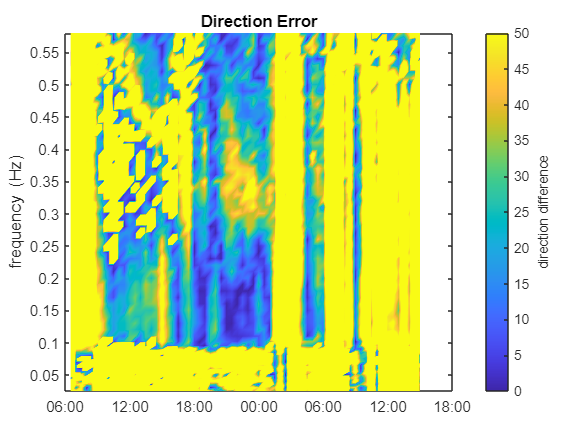

hist =     0.0250    0.0300    0.0350    0.0400    0.0450    0.0500    0.0550    0.0600    0.0650    0.0700    0.0750    0.0800    0.0850    0.0900    0.0950    0.1013    0.1100    0.1200    0.1300    0.1400    0.1500    0.1600    0.1700    0.1800    0.1900    0.2000    0.2100    0.2200    0.2300    0.2400    0.2500    0.2600    0.2700    0.2800    0.2900    0.3000    0.3100    0.3200    0.3300    0.3400    0.3500    0.3600    0.3700    0.3800    0.3900    0.4000    0.4100    0.4200    0.4300    0.4400
    0.0083    0.0086    0.0085    0.0082    0.0082    0.0085    0.0081    0.0079    0.0079    0.0078    0.0078    0.0079    0.0079    0.0088    0.0102    0.0109    0.0102    0.0096    0.0096    0.0093    0.0096    0.0096    0.0102    0.0098    0.0100    0.0098    0.0104    0.0096    0.0098    0.0093    0.0093    0.0089    0.0089    0.0088    0.0089    0.0088    0.0091    0.0086    0.0085    0.0088    0.0083    0.0088    0.0085    0.0088    0.0089    0.0093    0.0091    0.0098    0.0100  

%direction histograms
hist = dir_histogram(cdip, wgMeanDir, corr)

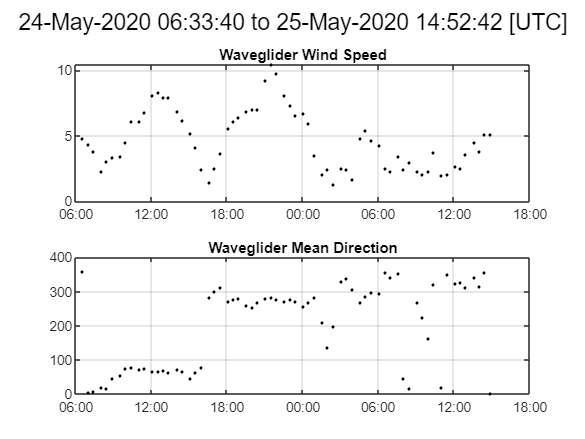

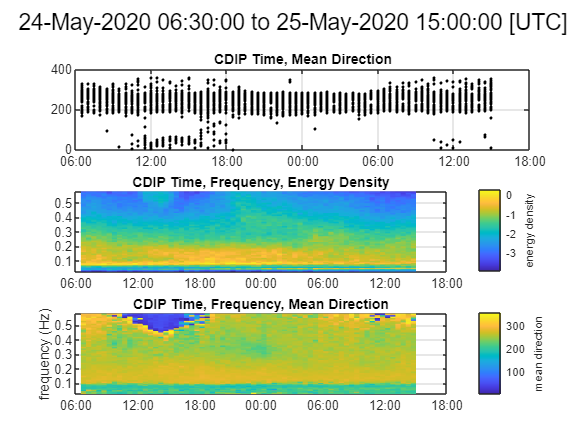

%pcolor plot
pcolor_plot(wgt, wgWind, wgMeanDir, cdip)

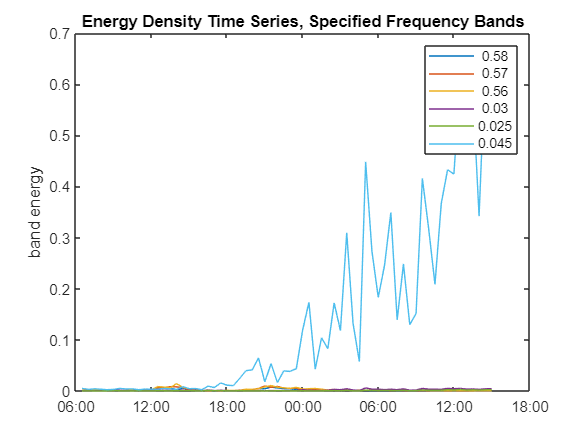

%energy density time series for selected frequency bands
freqplot(cdip, corr)